# **均匀平面波的传播**

**        为了解决电磁理论概念抽象、时空分布复杂等教学难题，本章介绍MATLAB在该领域驻波行波、电磁波的反射与透射等方面动画演示中的应用。主要介绍 MATLAB 动画技术分类、特点和实施步骤并通过实例为其教学应用提供指导和借鉴。在 MATLAB中实现动画制作需要用到getframe、implay和VideoWriter等函数，本章先简单个绍相关函数，然后再运用函数完成实例演示。**

**        MATLAB中，创建动画的过程分两步：**

- **第一步，调用 getframe 函数生成每个帧的信息。getframe 函数可以捕捉每一个帧画面，并将画面数据保存为一个结构。一般配合 for 循环语句得到一系列动画帧，并按顺序存储于一个阵列中，从而完成动画矩阵的建立。**

- **第二步，调用 VideoWriter 函数将阵列中的一系列动画帧转换成视频 avi 文件这样可以实现脱离 MATLAB 环境的动画播放。如果需要实时播放而不保存在文件中，则使用 implay 命令播放这些动画序列即可。**

**        编程的基本思路如下：定义时间变量、空间变量和相应的函数式通过循环不断增加时间变量，作图并保持一定时间后擦除原图，再重新作图，并在一段时间内连续演示，这样就形成了动画。**

**        在理想介质中传播的电磁波，其电场和磁场没有传播方向上的纵向分量，而只有与传播方向垂直的横向分量，且场量在横向截面上分布均匀，故这类电磁波称为均匀平面波，又可称为横电磁(Transvers Electromagnetic wave，TEM)波。均匀平面波的电场矢量 E 和磁场矢量 H 在时间上同相位，在空间上互相垂直。**

**        为讨论方便，先考虑沿 z 方向行进的波,若电场只有**$$$E _ { x }$$$**分量,则磁场只有**$$$H _ { y }$$$**分量，其瞬时值可以写为**


$$E(z,t)=E_m \cos (\omega t-kz)e_x$$


**其中**


$$$$Z = \frac { E } { H } = \frac { \omega \mu } { k } = \sqrt { \frac { \mu } { \varepsilon } }$$$$


**为电磁波在介质中的波阻抗，此值取决于媒质参量 **$\varepsilon$** 和 **$\mu$** 。在自由空间中，波阻抗为**


$$$$Z _ { 0 } = \sqrt { \frac { \mu _ { 0 } } { \varepsilon _ { 0 } } } = 120 \pi = 377 \Omega$$$$


**        计算上述表达式，并用quiver函数绘制箭头图，使用getframe函数捕捉动画帧后可将传播过程制作成视频。**

clc
clear
t = 0;
u0 = 1 * 4*pi*1e-7;      %磁导率
e0 = 1 * (1e-9/(36*pi)); %电介质常数
Z0 = sqrt(u0/e0);        %波阻抗
f = 1e+8;                %入射波频率
w = 2*pi*f;              %入射波角频率
k = w*sqrt(u0*e0);       %波数
phi_E = 0;               %电场初始相位
phi_H = 0;               %磁场初始相位
EE = 50;                 %电场幅度
HH = EE/Z0;              %磁场幅度
x = 0:0.1:10;            %横坐标序列
nill = zeros(size(x));   
for i=1:150
    E=EE*cos(w*t*1e-9 - k*x + phi_E);	%电场Ey表达式
    H=HH*cos(w*t*1e-9 - k*x + phi_H);  %磁场Hz表达式
    quiver3(x,nill,nill,nill,E,nill, 'r ');	%沿x轴方向，绘制电场箭头图
    hold on	%保持
    quiver3(x,nill,nill,nill,nill,H, 'b ');	%沿x轴方向，绘制磁场箭头图
    axis([0,10,-1,1,-1,1]); view(20,40); 	%观察范围和视角
    mov(i)=getframe(gcf);	%捕捉动画帧
    t=t+0.05;
    hold off
    xlabel('传播方向');
    ylabel('电场Ey');
    zlabel('磁场Hz');
    title('平面电磁波传播示意图')
    drawnow
end 
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **动态展示**

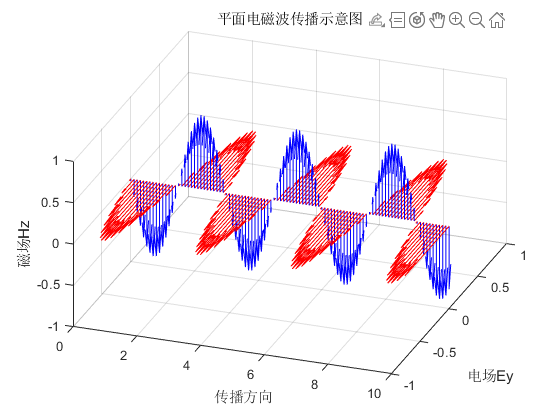

implay(mov);

- **保存为视频文件**

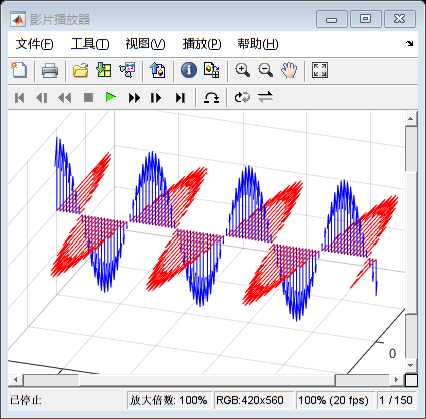

v=VideoWriter('均匀平面波.avi','Motion JPEG AVI');    %和前面的循环配合，实现动画输出为avi文件
open(v)

writeVideo(v,mov)
close(v)